Start fresh, and load all the data

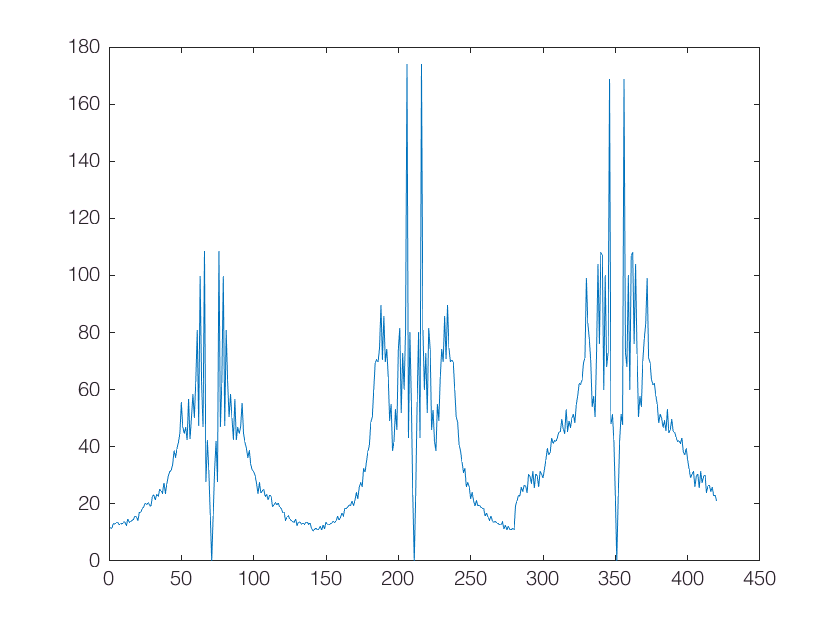

clear all
clf
load allData.mat
dataMatrixRaw = dataMatrix;
dataMatrix = abs(dataMatrix);
nClasses = length(testList);
testMatrix = abs(testMatrix);
%Find the average and take it out
meanGait = mean(dataMatrix,2);
plot(abs(meanGait));

dataMatrix = dataMatrix-meanGait;
testMatrix = testMatrix-meanGait;

Eigenstuff time. We have the vectors matrix, and will pull out the eigen vectors, eigen values, and more eigen vectors I think. U is the matrix of eigenvectors.

Then, make a matrix of coefficients.

[U,S,V] = svd(dataMatrix,'econ');
U = U(:,1:nClasses-1);
coeffMatrix = U'*dataMatrix;

classes =  reshape(coeffMatrix, size(coeffMatrix,1), 4, nClasses);
classes =  classes - mean(classes, 2);
Sc = zeros(size(classes,1));
for i=1:nClasses
    Sc = Sc + classes(:,:,i)*classes(:,:,i)';
end

[V, D] = eig(coeffMatrix*coeffMatrix', Sc);
V = V(:,1:end);
fisherMatrix = V'*coeffMatrix; 

sizeTr = length(trainList);
sizeTe = length(testList);

A good idea to plot one eigenvector to see if it makes sense

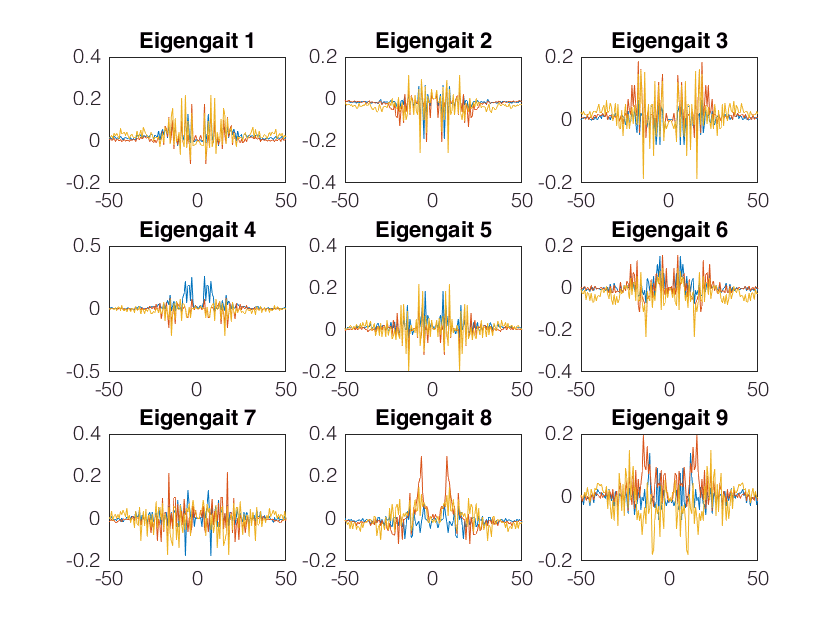

clf
for i = 1:9
    subplot(3,3,i)
    eigenVictim = U(:,i);
    f = linspace(-50,50,length(eigenVictim)/3);
    plot(f,reshape(eigenVictim,[],3));
    title(strcat('Eigengait',{' '},int2str(i)));
end

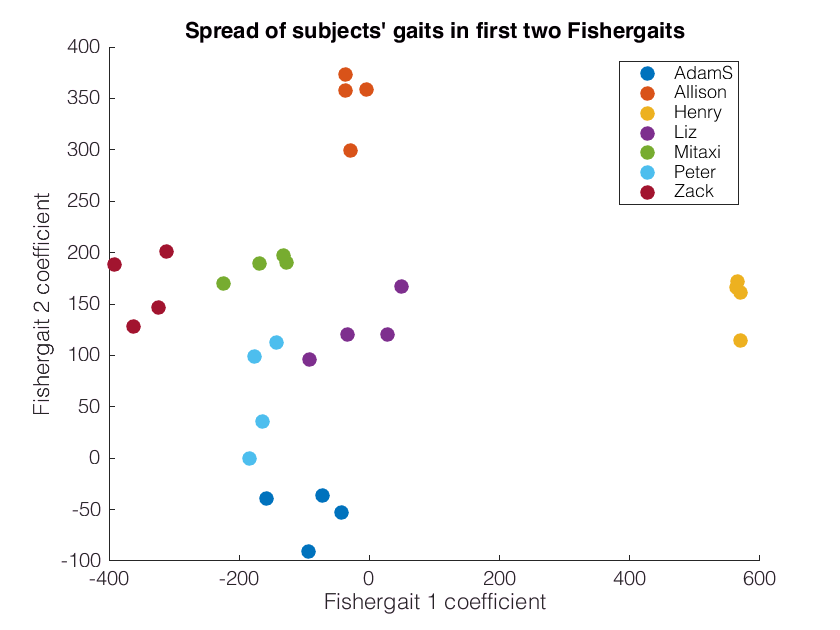

clf
hold on
for i=round(linspace(1, nClasses, 7))
    pts = fisherMatrix(1:2,i*4-3:i*4);
    name = char(testList(i));
    plot(pts(1,:),pts(2,:),'.', 'DisplayName', name(1:end-4), 'MarkerSize', 25);
end
legend('Show', 'Location', 'Best')
xlabel('Fishergait 1 coefficient');
ylabel('Fishergait 2 coefficient');
title('Spread of subjects'' gaits in first two Fishergaits');

Test a data

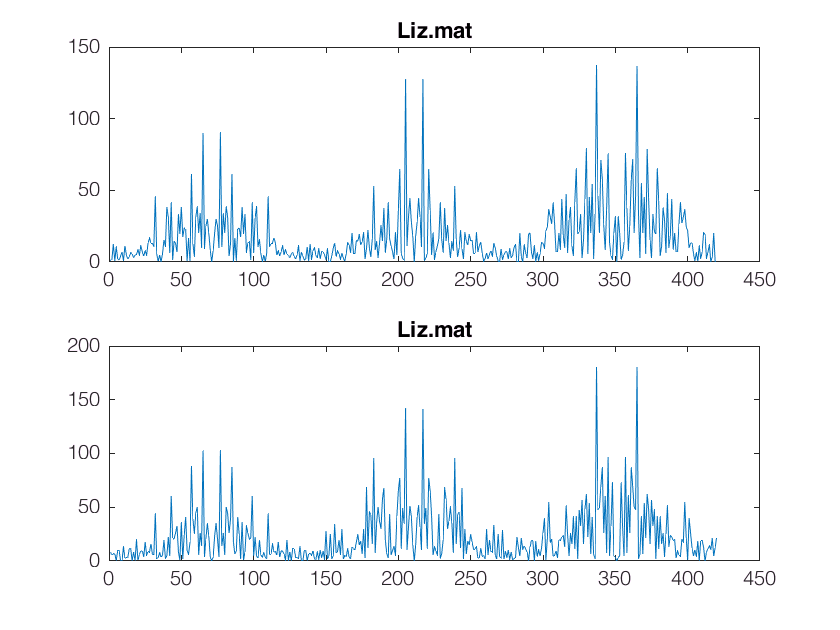

clf
pick = 14;
testGait = testMatrix(:,pick);
testAnswer = testList(pick);
testCoeff = U'*testGait;

% find closest match index for just the one gait
differences = zeros(1,sizeTr);
for i = 1:sizeTr
    differences(i) = norm(coeffMatrix(:,i)-testCoeff);
end
[minComparison, indexGuessed] = min(differences);
subplot(2,1,1)
plot(abs(testGait));
title(testAnswer)
subplot(2,1,2)
plot(abs(dataMatrix(:,indexGuessed)));
title(trainList(indexGuessed));

amirite = zeros(1,sizeTe);
for pick = 1:sizeTe
    differences = zeros(1,sizeTr);
    testGait = testMatrix(:,pick);
    testAnswer = testList(pick);
    testCoeff = U'*testGait;
    for i = 1:sizeTr
        differences(i) = norm(coeffMatrix(:,i)-testCoeff);
    end
    [minComparison, indexGuessed] = min(differences);
    amirite(pick) = isequal(testList(pick),trainList(indexGuessed));
end
mean(amirite)

ans = 0.9630